# 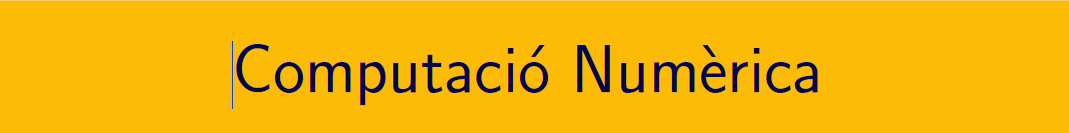

================================================================================

# Pràctica 10. Integració aproximada de funcions i dades (I).

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document .pdf i en el document **CN_exercicis_tema5_2.pdf**, els podeu trobar en el campus virtual. 

### Bloc 1. MATLAB® - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html). 

Per al mètode de Simpson, podeu fer ús de l'expressió  $ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$que relaciona la fórmula dels trapezis i la regla de Simpson. També podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files) (revisar el codi)

### Bloc 2.  MATLAB® - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Bloc 3.  MATLAB® - Integració adaptativa

La partició de l'interval d'integració es construiex de tal manera que  `abs(q - Q) <= max(AbsTol,RelTol*abs(q)), amb q el valor calculat i Q el valor exacte. Consulteu `[integral](https://www.mathworks.com/help/matlab/ref/integral.html) en la documentació de MATLAB®

Cleve Moler, entre els seus codis del llibre *Numerical computing with Matlab* ens ha preparat una explicació gràfica del procediment. 

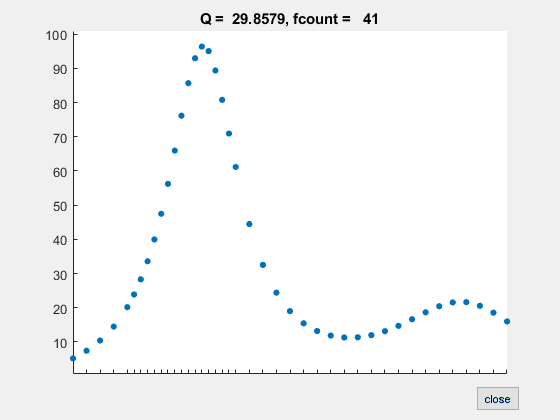

quadgui(@(x)humps(x),0,1,1.0e-2)

integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

ans =        29.858


### Bloc 4.  MATLAB® - Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

## APRENEM .....

### Exercici 1. Aplicació dades discretes

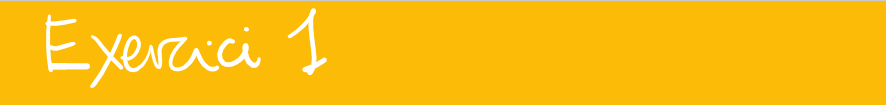

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

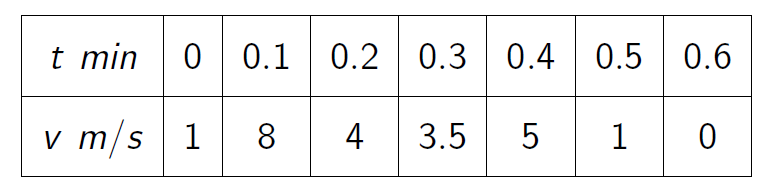

time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];

- Representa gràficament les dades de la taula

plot(time,vel,'ko', 'LineWidth',2), title('temps i velocitat mobil')

- Explica l'estratègia i dona el resultat pel mètode del punt mig

- Explica l'estratègia i dona el resultat pel mètode dels trapezis

- Explica l'estratègia i dona el resultat pel mètode de Simpson

### Exercici 2. Aplicació per funcions - Fórmules simples

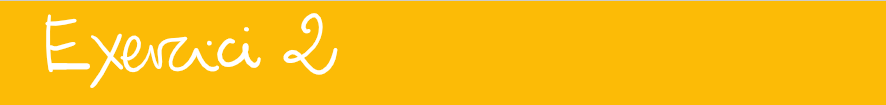

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


vc = pi/2
f = @(x)2./(1+x.^2);

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

a = 0; b = 1; h = b - a; pm = (a + b)/2, I_p = f(pm)*h, E_p = abs(I_p - vc)

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$(simple)

a = 0; b = 1; h = b - a; I_t = h/2*(f(a) + f(b)), E_t = abs(I_t - vc), ratio = E_t/E_p

vc = 1.5708

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

a = 0; b = 1; h = (b - a)/2; pm = (a + b)/2, I_s = h/3*(f(a)+4*f(pm)+f(b)), E_p = abs(I_s - vc)

### Exercici 3. Aplicació per funcions - Fórmules compostes

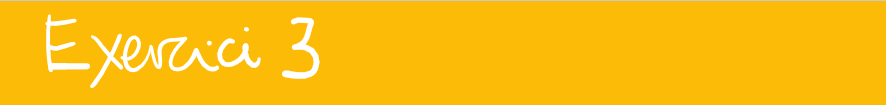

Podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files)

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


clearvars;

pm = 0.5000

I_p = 1.6000

E_p = 0.0292

f = @(x)2./(x.^2 + 1)
vc = pi/2

I_t = 1.5000

E_t = 0.0708

ratio = 2.4242

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

a = 0; b = 1; I_p = midp(f,a,b,8), E_p = abs(I_p - vc)

pm = 0.5000

I_s = 1.5667

E_p = 0.0041

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

I_t = trap(f,a,b,8), E_t = abs(I_t - vc), ratio = E_t/E_p

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (2 subintervals)

I_s = simp(f,a,b,2), E_p = abs(I_s - vc)

f = function_handle with value:
    @(x)2./(x.^2+1)


### Exercici 4. Funcions amb singularitats

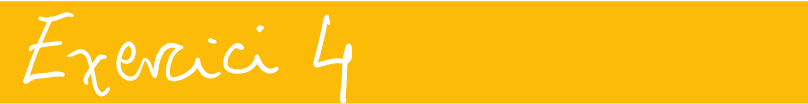

Calculeu $\displaystyle \int_0^{1} \frac{\sin t}{t}\,dt  \approx 0.946083070367 \pm 0.5e\!-\!12$

- Valor correcte

clearvars

vc = 1.5708

format longG
a=0;b=1;

I_p = 1.5714

E_p = 6.5104e-04

f=@(x)sin(x)./x;
vc = integral(f,a,b,"RelTol",5e-13)

I_t = 1.5695

E_t = 0.0013

ratio = 2.0000

- Regla del punt mig composta. Quants subintervals cal pendre?

I_p = midp(f,a,b,2048), E_p = abs(I_p - vc)

I_s = 1.5708

E_p = 1.2013e-05

- Regla dels trapezis composta. Quants subintervals cal pendre?

I_t = trap(@fun,a,b,2048), E_t = abs(I_t - vc)
I_s = simp(@fun,a,b,2048), E_s = abs(I_s - vc)
format shortG
[R,h] = romberg(@fun,a,b,6); % 1a columna -> trapezi; 2a columna -> Simpson
[h',R]

vc =          0.946083070367183


aux = [h', tril(abs(R-vc))]

### Exercici 5. Mètode de Romberg

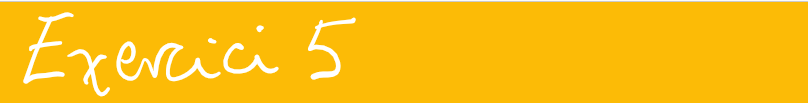

Calculeu mitjançant romberg$\displaystyle \int_0^{0.8} \frac{\sin t}{t}\,dt  \approx 0.772095 \pm 0.5e\!-\!6$

Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

I_p =          0.946083073359025


E_p =       2.99184244045847e-09


Resposta 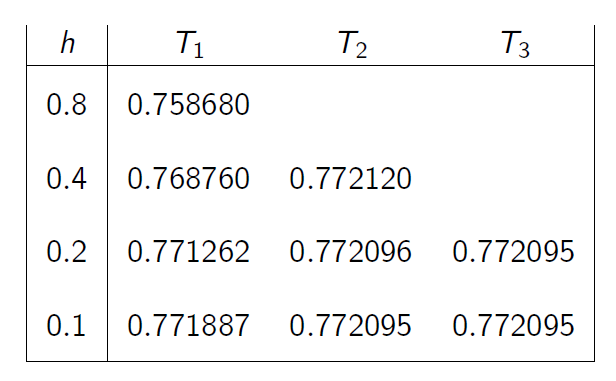

### Exercici 6. Mètode de Montecarlo

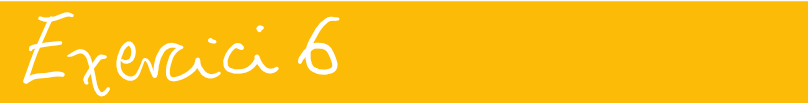

Calculeu els  valors  de    $\displaystyle\int_0^1 x dx = 1/2\,, \quad
\displaystyle\int_0^1 x^2 dx = 1/3\,, \quad
\displaystyle\int_0^4 x dx = 8\,, \quad
\displaystyle\int_{-1}^1 x dx = 1\,.

$

- Tipus I (valor esperat)

- Tipus II (hit or miss)

I_t =            0.9460830643835


E_t =       5.98368277149319e-09


## AUTOAVALUACIÓ ....

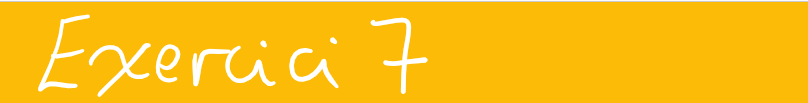

Calculeu la integral $\displaystyle I=\int_{-1}^{1} e^{-x^2}\,dx\,$

- a) Fent ús del mètode dels trapezis per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

format shortG

I_s =          0.946083070367186


E_s =       2.55351295663786e-15


vc = sqrt(pi)*erf(1)
a = 0; b = 1; k = 0:5; n = 2.^k
f = @(x) exp(-x.^2);

ans =             1      0.92074            0            0            0            0            0
          0.5      0.93979      0.94615            0            0            0            0
         0.25      0.94451      0.94609      0.94608            0            0            0
        0.125      0.94569      0.94608      0.94608      0.94608            0            0
       0.0625      0.94599      0.94608      0.94608      0.94608      0.94608            0
      0.03125      0.94606      0.94608      0.94608      0.94608      0.94608      0.94608


for i = 0:5

aux =             1     0.025348            0            0            0            0            0
          0.5    0.0062898   6.2812e-05            0            0            0            0
         0.25    0.0015695   3.8636e-06   6.6304e-08            0            0            0
        0.125   0.00039221   2.4052e-07   1.0163e-09    2.004e-11            0            0
       0.0625    9.804e-05   1.5018e-08   1.5804e-11   7.6494e-14   1.7764e-15            0
      0.03125   2.4509e-05   9.3838e-10   2.4658e-13   3.3307e-16   1.1102e-16   1.1102e-16


    T(i+1) = 2*trap(f,a,b,2^i);
end
aux = abs(T - vc);
ratio = aux(1:end-1)./aux(2:end); ratio = [ratio, 4];
disp([k', 2*n', T', aux', ratio'])

- b) Fent ús del mètode de Simpon per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

for i = 0:5
    S(i+1) = 2*simp(f,a,b,2^i);
end
aux = abs(S - vc);
ratio = aux(1:end-1)./aux(2:end); ratio = [ratio, 16];
disp([k', n', S', aux', ratio'])

- c) Apliqueu el mètode de Romberg, fent ús dels resultats de l'apartat a) 

[R,h] = romberg(f,a,b,6); % 1a columna -> trapezi; 2a columna -> Simpson
TR = [h', 2*R]
aux = tril(abs(2*R-vc))

- d) Fent ús de mètodes de simulació de MonteCarlo, per mostres de tamany $$M={10^k},\ \ 1\leq k\leq 7.$$

- e)  Doneu els decimals exactes i les xifres significatives del les vostres aproximacions, sabent que  $$\displaystyle\int_0^t e^{-x^2}\,dx\, = \sqrt{\pi}\,erf\left(t\right).$$ Consulteu l'ajuda de Matlab per la funció `erf.`

`Document preparat per M. Àngela Grau Gotés - 3 de maig de 2023`

% Codis de les funcions 

% Usage: r = midp(f,a,b,n)
% Composite midpoint rule (1-point open Newton-Cotes)
%

vc =        1.4936


% Input:

n =      1     2     4     8    16    32


% f - Matlab inline function 
% a,b - integration interval
% n - number of subintervals (panels)
%
% Output:
% r - computed value of the integral
%

            0            2       1.3679      0.12577       4.0692
            1            4       1.4627     0.030908       4.0244
            2            8        1.486    0.0076801       4.0062
            3           16       1.4917     0.001917       4.0016
            4           32       1.4932   0.00047907       4.0004
            5           64       1.4935   0.00011976            4



% Examples:
% r=midp(@sin,0,1,10);
% r=midp(@myfunc,0,1,10);          here 'myfunc' is any user-defined function in M-file
% r=midp(inline('sin(x)'),0,1,10);
% r=midp(inline('sin(x)-cos(x)'),0,1,10);


function r = midp(f,a,b,n)

            0            1       1.4944   0.00071259       11.403
            1            2       1.4937   6.2494e-05        15.72
            2            4       1.4937   3.9754e-06        15.95
            3            8       1.4936   2.4925e-07       15.989
            4           16       1.4936   1.5589e-08       15.997
            5           32       1.4936   9.7449e-10           16



    h = (b - a) / n;
    x = a + h * 0.5;
    r = 0;

TR =             1       1.3679            0            0            0            0            0
          0.5       1.4627       1.4944            0            0            0            0
         0.25        1.486       1.4937       1.4937            0            0            0
        0.125       1.4917       1.4937       1.4936       1.4936            0            0
       0.0625       1.4932       1.4936       1.4936       1.4936       1.4936            0
      0.03125       1.4935       1.4936       1.4936       1.4936       1.4936       1.4936


    for i=1:n

aux =       0.12577            0            0            0            0            0
     0.030908   0.00071259            0            0            0            0
    0.0076801   6.2494e-05   1.9154e-05            0            0            0
     0.001917   3.9754e-06   7.4195e-08   2.2866e-07            0            0
   0.00047907   2.4925e-07   8.3438e-10   3.3008e-10   5.6533e-10            0
   0.00011976   1.5589e-08    1.195e-11    1.104e-12   1.8607e-13   3.6637e-13


        r = r + f(x);
        x = x + h;
    end
    r = r * h;
end

function y = fun(x)
    y = sin(x)./(x);
    if isnan(y)
        y = 1;
    end
end
        

% Usage: r = trap(f,a,b,n)
% Composite trapezoid rule (2-point closed Newton-Cotes)
%
% Input:
% f - Matlab inline function 
% a,b - integration interval
% n - number of subintervals (panels)
%
% Output:
% r - computed value of the integral
%
% Examples:
% r=trap(@sin,0,1,10);
% r=trap(@myfunc,0,1,10);          here 'myfunc' is any user-defined function in M-file
% r=trap(inline('sin(x)'),0,1,10);
% r=trap(inline('sin(x)-cos(x)'),0,1,10);

function r = trap(f,a,b,n)
    h = (b - a) / n;
    r = f(a) * 0.5;
    x = a + h;
    for i = 1 : n-1
        r = r + f(x);
        x = x + h;
    end
    r = r + f(b) * 0.5;
    r = r * h;
end

% Usage: r = simp(f,a,b,n)
% Composite Simpson's rule (3-point closed Newton-Cotes)
%
% Input:
% f - Matlab inline function 
% a,b - integration interval
% n - number of subintervals (panels)
%
% Output:
% r - computed value of the integral
%
% Examples:
% r=simp(@sin,0,1,10);
% r=simp(@myfunc,0,1,10);          here 'myfunc' is any user-defined function in M-file
% r=simp(inline('sin(x)'),0,1,10);
% r=simp(inline('sin(x)-cos(x)'),0,1,10);

function r = simp(f,a,b,n)
    h = (b - a) / (n * 2);
    r = f(a);
    x = a + h;
    for i = 1 : n-1
        r = r + 4 * f(x);
        x = x + h;
        r = r + 2 * f(x);
        x = x + h;
    end
    r = r + 4 * f(x);
    r = r + f(b);
    r = r * h/3;
end

% Usage: r = romberg(f,a,b,n)
% Romberg integration
%
% Input:
% f - Matlab inline function 
% a,b - integration interval
% n - number of rows in Romberg tableau
%
% Output:
% r - Romberg tableau containing the computed values of the integral
%
% Examples:
% r=romberg(@sin,0,1,5);
% r=romberg(@myfunc,0,1,5);          here 'myfunc' is any user-defined function in M-file
% r=romberg(inline('sin(x)'),0,1,5);
% r=romberg(inline('sin(x)-cos(x)'),0,1,7);

function [r,h] = romberg(f,a,b,n)
    h = (b - a) ./ (2.^(0:n-1));
    r(1,1) = (b - a) * (f(a) + f(b)) / 2;
    for j = 2:n
        subtotal = 0;
        for i = 1:2^(j-2)
            subtotal = subtotal + f(a + (2 * i - 1) * h(j));
        end
        r(j,1) = r(j-1,1) / 2 + h(j) * subtotal;
        for k = 2:j
            r(j,k) = (4^(k-1) * r(j,k-1) - r(j-1,k-1)) / (4^(k-1) - 1);
        end
    end
end